close all
clear variables
spectra = importdata("spectra.csv");
lambdaDelta = importdata("lambda_delta.csv");
lambdaStart = importdata("lambda_start.csv");
starNames = importdata("star_names.csv");

lambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/c

nObs = size(spectra, 1);
nStars = size(starNames, 1);
lambdaEnd = lambdaStart + (nObs - 1)*lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

i = 0;
speed = [1:nStars];
lambdaHa = [1:nStars];
z = [1:nStars];

for i = 1:nStars
    s = spectra(:, i);
    [sHa, idx] = min(s);
    lambdaHa(i) = lambda(idx);
    z(i) = (lambdaHa(i) - lambdaPr)/ lambdaPr;
    speed(i) = z(i) * speedOfLight;
end 
moveaway = starNames(speed < 0);

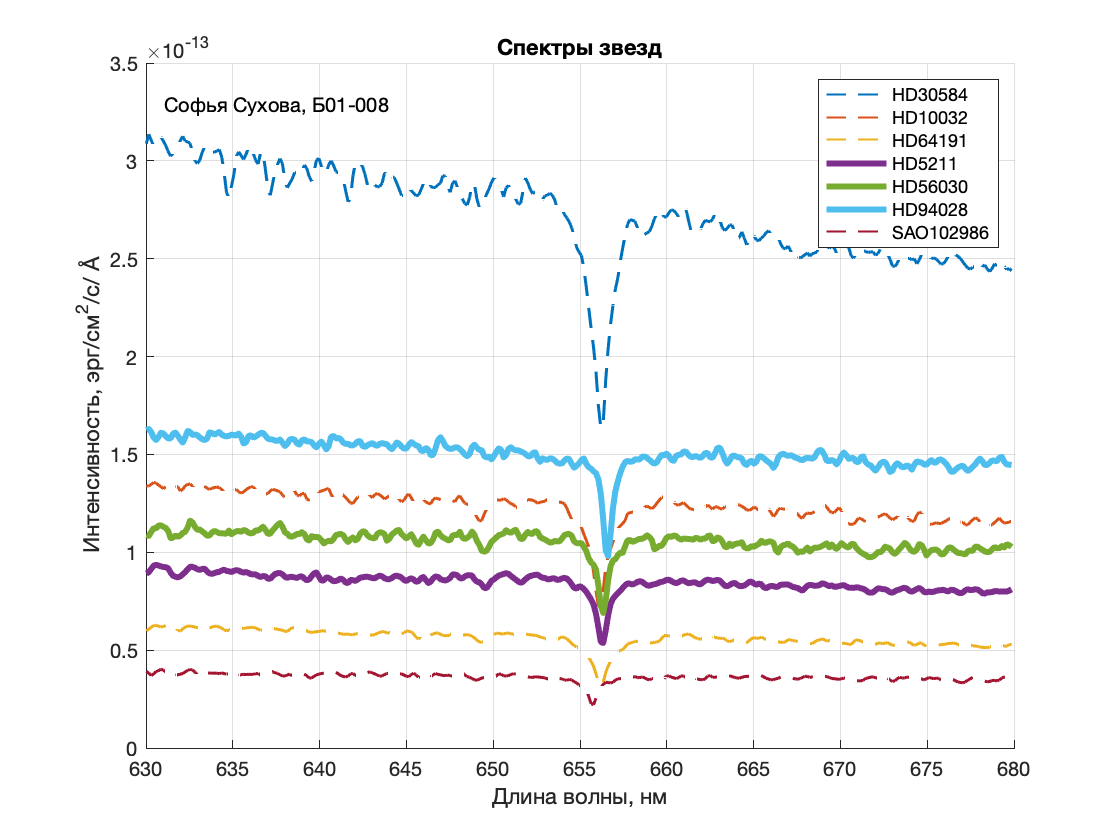

fg1 = figure;
hold on
for i = 1:nStars
    s = spectra(:, i);
    if speed(i) > 0
        plot(lambda,s, 'LineWidth',3);
    else
        plot(lambda,s,'--','LineWidth',1);
    end
end
grid on;
xlabel('Длина волны, нм');
ylabel(['Интенсивность, эрг/см^2/с/ ', char(197)]);
title('Спектры звезд');
legend(starNames(:,1), 'Location', 'northeast');
text(lambdaStart + 1, max(max(spectra))*1.05, ["Софья Сухова, Б01-008"]);
set(fg1, 'Visible', 'on');
hold off

saveas(fg1, 'spectra.png');